**Noise Generation Low Freq**

clear all
close all
clc

fl=600;
[x,fs]=audioread('Clean.mp3');
n=length(x); 
t=(1:n)/fs;
z=cos(2*pi*fl*t);

sound(z,fs)
audiowrite('Noise.wav',z,fs);

**Audio Mixing**

close all
clc

[x,fs]=audioread('Clean.mp3');
[z,fs]=audioread('Noise.wav');

y=x+z;

audiowrite('Test.wav',y,fs)


sound(x,fs)
sound(y,fs)

**Filter Design High Pass**

close all
clc

[z,fs]=audioread('Test.wav');

y = highpass(z,fl+150,fs)

y =     0.5324
    0.5237
    0.5037
    0.4735
    0.4345
    0.3880
    0.3356
    0.2791
    0.2201
    0.1603



[x,fs]=audioread('Clean.mp3');

sound(x,fs)
sound(y,fs)

audiowrite('Output.wav',y,fs);

**Audio Amplifier**

[x, fs] = audioread('Clean.wav');
[y,Fs] = audioread('Output.wav');
[z,fs]=audioread('Test.wav');

y=y*10

y =     5.3241
    5.2368
    5.0369
    4.7351
    4.3445
    3.8797
    3.3563
    2.7908
    2.2012
    1.6031



sound(x,Fs)
sound(z,Fs)
sound(y,Fs)

audiowrite('Output.wav',y,fs);

**Plot And Response**

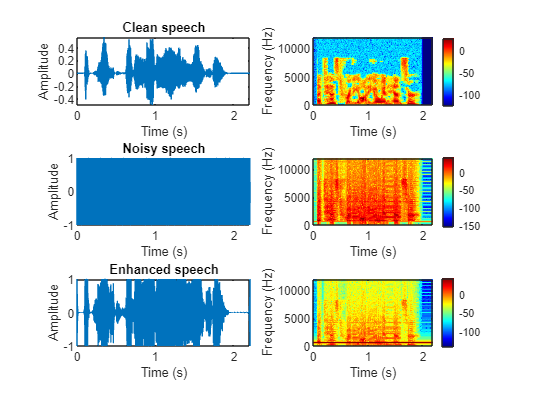

[x, fs] = audioread('Clean.wav');
[y,Fs] = audioread('Output.wav');
[z,fs]=audioread('Test.wav');

subplot(3,2,1)
plotWave_YW(0,x,fs,'time',1);
title('Clean speech')
subplot(3,2,2)
plotWave_YW(0,x,fs,'freq');

subplot(3,2,3)
plotWave_YW(0,z,fs,'time',1);
title('Noisy speech')
subplot(3,2,4)
plotWave_YW(0,y,fs,'freq');

subplot(3,2,5)
plotWave_YW(0,y,fs,'time',1);
title('Enhanced speech')
subplot(3,2,6)

plotWave_YW(0,z,fs,'freq');

**Gaussian Noise**

clear all
close all
clc

fh=10000;
[x,fs]=audioread('Clean.mp3');

xn=awgn(x,20,'measured');

sound(xn,fs)
audiowrite('Noise.wa1v',xn,fs);

Error using audiowrite>validateExtension
Incorrect file extension for file Noise.wa1v.
Supported extensions are:
	.flac
	.oga
	.ogg
	.wav

Error in audiowrite>validateFilename (line 398)
validateExtension(filepath.Extension,filename)

Error in audiowrite (line 168)
    [props.filename, fileExisted] = validateFilename( props.fil

**Wiener Filter**

close all
clc

[x, fs] = audioread('Clean.wav');
[z] = audioread('Noise.wav');
y = noiseReduction_YW(z, fs);

audiowrite('Output.wav',y,fs);

**Audio Amplifier**

[x, fs] = audioread('Clean.wav');
[y,Fs] = audioread('Output.wav');
[z,fs]=audioread('Noise.wav');

y=y*10

sound(x,Fs)
sound(y,Fs)
sound(z,Fs)

audiowrite('Noise.wav',y,fs);

**Plot And Response**

[x, fs] = audioread('Clean.wav');
[y,Fs] = audioread('Output.wav');
[z,fs]=audioread('Noise.wav');

subplot(3,2,1)
plotWave_YW(0,x,fs,'time',1);
title('Clean speech')
subplot(3,2,2)
plotWave_YW(0,x,fs,'freq');

subplot(3,2,3)
plotWave_YW(0,z,fs,'time',1);
title('Noisy speech')
subplot(3,2,4)
plotWave_YW(0,z,fs,'freq');

subplot(3,2,5)
plotWave_YW(0,y,fs,'time',1);
title('Enhanced speech')
subplot(3,2,6)
plotWave_YW(0,y,fs,'freq');